value_loadcase = 10.5e3;
loadscale = 20/value_loadcase;

for num_loadcase=1:5
    loadcase = bridgeobj.getLoadCases(num_loadcase,value_loadcase);
    bridgeobj.addLoad(loadcase,"Name",sprintf('工况%n',num_loadcase));
    fig = figure;
    ax = axes;
    fig.Position = [100,100,1400,300];
    ax.Position = [0.01,0.01,0.99,0.99]

ax =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0100 0.0100 0.9900 0.9900]
            Units: 'normalized'

  显示 所有属性


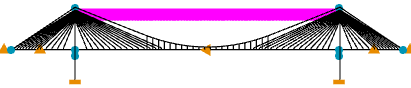

    bridgeobj.plot('Figure',fig,'Axis',ax,...
                   'LoadScale',loadscale,...
                   'LoadLineWidth',2,...
                   'LoadOffset',[0,0,80]);
    ax.Visible = 'off';
    ax.DataAspectRatio = [1,1,1];
    view([0,-1,0]);

    bridgeobj.removeLoadCase(num_loadcase);
    print(fig,sprintf('工况%d',num_loadcase),'-dpng','-r300');
end

bridgeobj.StructureCell_SideSpan{1}